# 日本の標高データをMATLABで活用 - モザイク結合 -

## はじめに

本件は[日本の標高データをMATLABで活用 - GeoTiff変換 -](https://qiita.com/Hernia_Baby/private/aa8f86f38e5f12f51c5b)の続きです。

先回はDEMデータをGeoTiffファイルにしました。

しかしきれいに繋がらなかったり、そもそも3次メッシュが一部欠損してたり…

これらを(0, 0) ~ (9,9)までの区画に当てはめて2次メッシュをきれいに結合します。

モザイク結合については[ラスターの統合 - モザイク](https://fme-casestudy.blogspot.com/2015/07/blog-post_11.html)を見てください。

### 今回やること

3次メッシュを100枚集めて2次メッシュにする。

以下は3次メッシュ5841-46-43を(4, 3)に当てはめているイメージ。

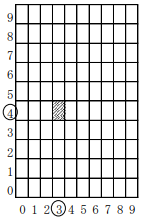

## フォルダを読み込む

先回作った5841-46-XXのメッシュでXXは(0, 0) ~ (9, 9)にそれぞれ当てはまる合計100このtifファイルがあるはずです。

まずは先回作ったtmpファイル内の中を見ていきましょう。

※このときtmp内に merge.tif 等の tif ファイルが入っていたらエラーを吐くので注意してください。

clc,clear,close all;

% path = '\PackDLMap\FG-GML-5841-46-DEM1A\tmp';
path = uigetdir();
fnames = dir(fullfile(path,"*.tif"));


path = fnames(1).folder;
file = {fnames.name}';
fsize =  length(file);

後は100枚のファイルを並べてモザイク結合を…

fprintf("tifファイルは%0iこ",fsize)

tifファイルは82こ

そうです。3次メッシュがない場合もあります。

今回のファイルだと00の次が10になっていることがわかります。

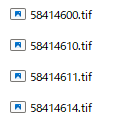

これは後で全てNaNのダミーデータを作って無理やり当てはめます。

## 2次メッシュに当てはめるための格子を作成する

まずは以下のような格子をcell配列で作ってそれぞれに3次メッシュ情報をぶち込めばOKです。

### 3次メッシュ番号を抜き出す

とはいえ、まずは番地に当てはめるために番号を抽出しましょう。

[~,name,~] = fileparts(file);
name = cell2mat(name);
rr  = str2double(string(name(:,end-1:end)));
disp(rr(1:4))

     0
    10
    11
    14



### 3次メッシュデータを決まった場所に格納する

次に全部Falseにした10×10の配列を作成します。

これは後でどこに3次メッシュデータがあるかを探索するように使います。

IDX1 = false(10);
IDX2 = IDX1;

10の位と1の位を分割し、1からスタートさせるよう加算します。

MATLABなので(1, 1)からスタートする必要があるため1を各桁に加算します。

digits = [floor(rr./10), rem(rr,10)] + 1;
disp(digits(1:4,:))

     1     1
     2     1
     2     2
     2     5



GeoTiffファイルを入れるため10×10のcell配列を作ります。

Rasters = cell(10);

最初のcell部分はTrueにしておきます。以下の部分だけTrueになりました。

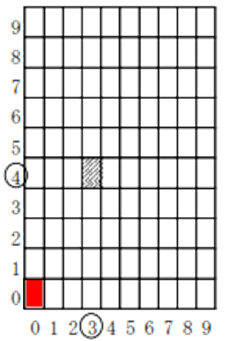

IDX1(digits(:,1), digits(:,2)) = true;

### データのない箇所を探す

データのあるファイルの出力先をIDX2であぶりだします。

idx1 = sub2ind(size(IDX1),digits(:,1),digits(:,2));
IDX2(idx1) = true;

わかりやすいように図示します。

データがない箇所を黒、データがある場所が白です。

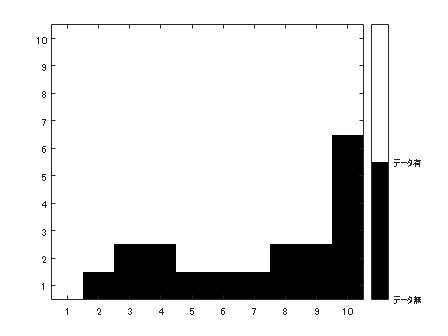

figure
image(IDX2)
axis xy
colormap([0, 0, 0; 1, 1, 1])
colorbar('Ticks',[0,1],'TickLabels',{'データ無','データ有'})

右下がデータないんですね。多分海だからでしょうね。

### データを読み込む

各GeoTIFFファイルを読み込み、緯度経度高度を各配列に格納します。

Lats = zeros(fsize,2);
Lons = Lats;
RSzs = Lats;

for ii = 1:length(idx1)
    [Z,Ref] = readgeoraster(fullfile(path,file{ii}),'OutputType','double');
    Rasters(idx1(ii)) = {Z};
    Lats(ii,:) = Ref.LatitudeLimits;
    Lons(ii,:) = Ref.LongitudeLimits;
    RSzs(ii,:) = Ref.RasterSize;
end

### データの欠損部分をNaNで埋める

排他的論理和でFalseとTrureを反転させます。

IDX3 = xor(IDX1,IDX2);

Raster内で埋める必要があるところを750×1125のNaN配列で埋めます。

idx2 = find(IDX3);
Rasters(idx2) = {nan(RSzs(1,:))};

残りは画像として排除していいのでNAN埋めします。

idx3 = find(~IDX1);
Rasters(idx3) = {nan(RSzs(1,:))};

### 画像データを上下逆にする

上下を反対にして一枚のdoubleデータにします。

MATLABでは左上が(0, 0)ですが、ここでの画像は左下が(0, 0)です。

check = flip(Rasters);
Rasters = cell2mat(flip(Rasters));
Rasters = Rasters(:,~all(isnan(Rasters),1));
Rasters = Rasters(~all(isnan(Rasters),2),:);

### モザイク結合

緯度・経度・高度情報(750×1125)をcell配列の決められた番地に格納していきます。

結合は [georefcells](https://jp.mathworks.com/help/map/ref/georefcells.html) で出来ます。

LatsLim = [min(Lats(:,1)), max(Lats(:,2))];
LonsLim = [min(Lons(:,1)), max(Lons(:,2))];
R = georefcells(LatsLim, LonsLim,size(Rasters),"ColumnsStartFrom","north");

MATLAB上で問題ないか見てみましょう。

% 1m間隔は重たい！やるならmファイルで実行しましょう。
% geoshow(uint8(Rasters),R)

## 出力

さて出力します。

geotiffwrite('GeoTiff_Merge.tif',single(Rasters),R,"CoordRefSysCode",'EPSG:6668')
disp('モザイク結合完了')

モザイク結合完了


## 出力結果

さて結果を見てみましょう。

今回もフリーソフト [QGIS](https://qgis.org/ja/site/) で確認します。

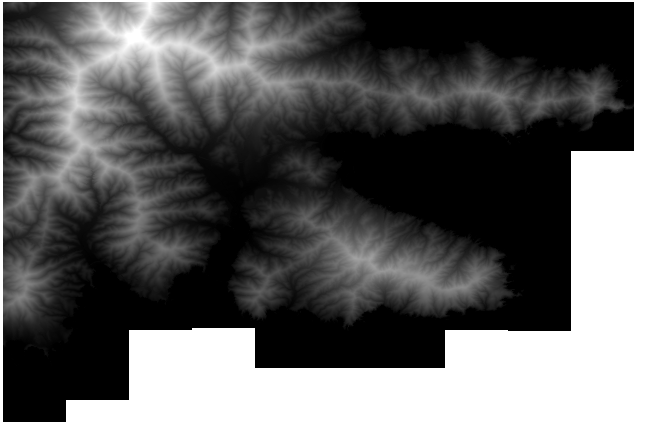

きちんとできていることがわかりました。

## おまけ

実はアプリも作ってます。

こちらは [waitbar](https://jp.mathworks.com/help/matlab/ref/waitbar.html) 等のメッセージボックスを入れてUIをあげてます。

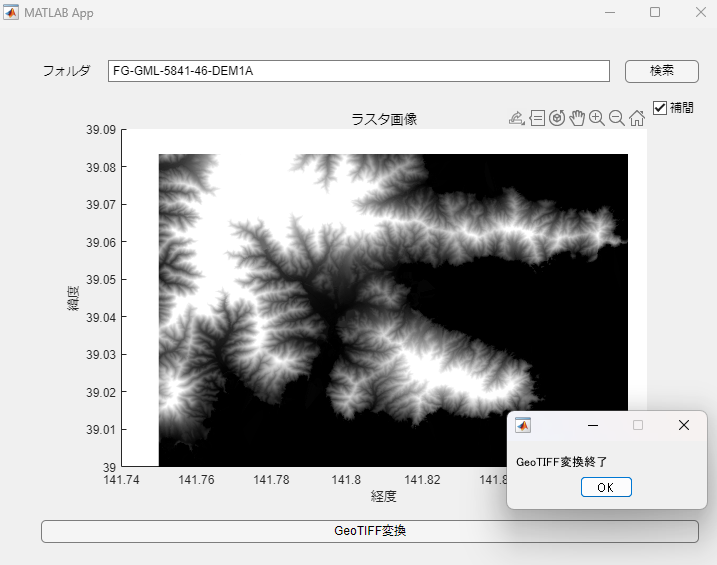

こいつはライトニングトーク用かなあ。

## 参考

- [基盤地図情報 数値標高モデル](https://fgd.gsi.go.jp/download/menu.php)

- [ラスターの統合 - モザイク](https://fme-casestudy.blogspot.com/2015/07/blog-post_11.html)

- [複数の画像を統合（モザイク）](https://www.youtube.com/watch?v=la_aOPP3vuQ&ab_channel=ESRI%E3%82%B8%E3%83%A3%E3%83%91%E3%83%B3)

- [【GIS】測地系、投影法、座標系、EPSGコードについてまとめてみた](https://qiita.com/asahina820/items/a1707cba749c1fb2b192)